# Exploring Derivatives

## Introduction

The **essence** of calculus is the **derivative**. The **derivative** is the instantaneous rate of change of a function with respect to one of its variables. This is equivalent to finding the slope of the tangent line to the function at a point.

You already have learned some methods to calculate derivatives of functions and MATLAB can assist you to confirm your results or analyse the behaivour of the derivative graphically.

In this activity we will use the commands [`syms`](https://au.mathworks.com/help/symbolic/syms.html) and [`diff`](https://au.mathworks.com/help/symbolic/differentiation.html) to calculate derivatives symbolically. 

## **Before starting**

Use the **MATLAB** **Live Editor** to **edit** and **run** this **Live Script** in your browser or your desktop.

- Read each section carefully. 

- Run the code within a section before starting to read the next. 

- To run the code from each section, position the *cursor* on the code with the mouse and then click on the **Run Section** button (from the toolstrip) or click on the blue stripe on left side of that section as shown below:

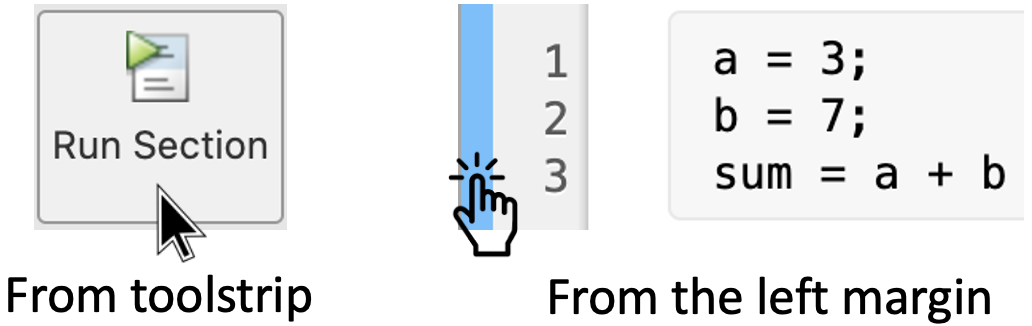

**Remark:** Run the code of each section from top to bottom, otherwise you may get an error.

- *The end of a section is indicated with a thin line, like the next one* -

## 1. Symbolic calculation of derivatives

To illustrate how to calculate derivatives in MATLAB, first we create a symbolic expression:

syms x            % Define the symbolic variable x
f = 1/(1 + x^2);  % Define the symbolic expression, i.e. f(x)

The command

diff(f)

$$ans = -\frac{2\,x}{{\left(x^{2}+1\right)}^{2}}$$

differentiates "`f`" with respect to "`x`". Run this section to see the result.

If there are more variables in our function, we can write:

syms x n
f = x^n + 2*n*x;
diff(f)

$$ans = 2\,n+n\,x^{n-1}$$

**Remark: **You can also specify the variable that you want to differentiate with respect to, i.e. `diff(f, n)`. Try it yourself! Modify the previous code to calculate the derivative with respect to "`n`".

## 2. Geometric relationship between $f\left(x\right)$ and $f^{\prime } \left(x\right)$

We can plot together the graphs of


$$f\left(x\right)=\frac{1}{1+x^2 }$$


and its derivative


$$f^{\prime } \left(x\right)=-\frac{2x}{{\left(1+x^2 \right)}^2 }$$


to observe the relationship between these. To do this we write:

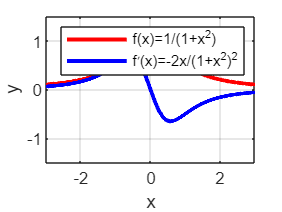

x = linspace(-3, 3, 1000); % Define domain
fun = 1./(1 + x.^2); % Calculate the function 
Dfun = -2*x./(1 + x.^2).^2; % Calculate the derivative 
plot(x, fun, 'r', x, Dfun, 'b', 'LineWidth', 2) % Plot function and derivative
legend('f(x)=1/(1+x^2)', 'f^{\prime}(x)=-2x/(1+x^2)^2')
xlabel('x'), ylabel('y'), grid on
axis([-3,3,-1.5,1.5])

**Remark:** Here we are using row vectors (also known as *arrays*) which means that the operations *multiplication*, *division* and *exponentiation* must have the *period *"`.`" before each operator: `*, /, ^`. Learn more about it here: [Arithmetic operations](https://au.mathworks.com/help/matlab/arithmetic-operators.html).

Now run this section to analyse the graphs of $f\left(x\right)$ and $f^{\prime } \left(x\right)$. What do you notice? 

## 3. Geometric exploration of derivatives of piecewise functions

Consider the function

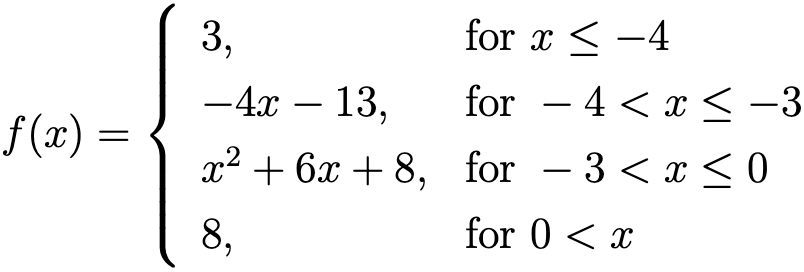

We would like to determine if $f\left(x\right)$ is differentiable at $x=-4,-3$ and $0$. But first let's have a look to its graph to observe how it changes. Notice also that $f\left(x\right)$ is a piecewise function so we need to find a way to define it in MATLAB.

### 3.1 Plotting Piecewise Functions: Using the `fplot` command

#### Symbolic plots

Here we will use a method that allows us to calculate the derivative of $f\left(x\right)$ symbolically with the help of the [`syms`](https://au.mathworks.com/help/symbolic/syms.html) and [`piecewise`](https://au.mathworks.com/help/symbolic/piecewise.html) commands. We write:

syms x   % Define symbolic variable

% Conditionally defined function
f = piecewise( ...
       x <= -4, 3, ...
       -4 < x & x <= -3, -4*x-13, ...
       -3 < x & x <= 0, x^2+6*x+8, ...
       0 < x, 8 ...
    )

$$f = \left\{ \begin{array}{cl} 3 & \text{ if }x\leq -4\\ -4\,x-13 & \text{ if }x\in \left(-4,-3\right]\\ x^{2}+6\,x+8 & \text{ if }x\in \left(-3,0\right]\\ 8 & \text{ if }0<x \end{array}\right.$$

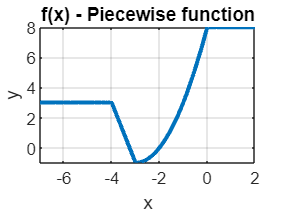


% Finally we plot the function within domain [-7,2]
fplot(x, f, [-7,2], 'LineWidth', 2)
xlabel('x'), ylabel('y'), grid on
title('f(x) - Piecewise function')

**Remark:** The three dots "`...`" tell MATLAB that the code on a given line continues on the next line. It is used so command lines don't stretch out too long to print or read easily.

**Optional: **We could also have plotted $f\left(x\right)$ without using symbolic variables by using the method described in Appendix A. 

Since we defined "f" as a *symbolic expression* we can easily calculate its derivative:

Df = diff(f)

$$Df = \left\{ \begin{array}{cl} 0 & \text{ if }x<-4\\ -4 & \text{ if }x\in \left(-4,-3\right)\\ 2\,x+6 & \text{ if }x\in \left(-3,0\right)\\ 0 & \text{ if }0<x \end{array}\right.$$

Run this section and analyse the results. What do you notice? 

### 3.2 Left-hand and Right-hand derivatives of piecewise functions

It is well known that the **absolute value** function


$$g\left(x\right)=\left\lbrace \begin{array}{ll}
-x & \textrm{for}\;x<0\\
x & \textrm{for}\;0\le x
\end{array}\right.$$


is not differentiable at $x=0$. This is clear when we analyse its left-hand and right-hand derivatives at $x=0$.

Recall that the **left-hand **and **right-hand derivatives **of a function $f$ at $x=a$ are defined by: 

$f_-^{\prime } \left(a\right)=\lim_{x\to a^- } \frac{f\left(x\right)-f\left(a\right)}{x-a}$  and  $f_+^{\prime } \left(a\right)=\lim_{x\to a^+ } \frac{f\left(x\right)-f\left(a\right)}{x-a}$

if these limits exist. Then:


$$f^{\prime } \left(a\right)=\lim_{x\to a} \frac{f\left(x\right)-f\left(a\right)}{x-a}$$


exists if and only if these one-sided derivatives exist and are equal, i.e.

$f_-^{\prime } \left(a\right)=f_+^{\prime } \left(a\right)$.

Thus, in MATLAB, first we need to determine symbolically the quotient


$$\frac{g\left(x\right)-g\left(0\right)}{x-0}$$


and then calculate the left-hand and right-hand limits as follows:

syms x   % Define symbolic variable x

% Conditionally defined function
g = piecewise( ...
       x < 0, -x, ...
       0 <= x, x ...
    )

$$g = \left\{ \begin{array}{cl} -x & \text{ if }x<0\\ x & \text{ if }0\leq x \end{array}\right.$$


% Now define the quotient (g(x)-g(0))/(x-0)
% with the help of the inbuilt MATLAB absolute value function, abs()
quotient = (g - abs(0))/(x - 0);

% Finally, calculate the one-sided limits
limit(quotient, x, 0, 'left')

$$ans = -1$$

limit(quotient, x, 0, 'right')

$$ans = 1$$

Run this section to see the results. Are these limits equal? Is $g\left(x\right)$ differentiable at $x=0$?

## 4. Hands on practice

Let's practice what we just learned.

### Activity 1:

Calculate the derivatives of the following functions:

- 
$$\frac{x^2 +1}{x-1}$$


- 
$$\left(2x+1\right)e^{-x^2 }$$


- 
$$\sin \left(\frac{x-1}{x+1}\right)$$


- 
$${\left(\cos \left(x\right)-2x\right)}^2$$


Write your code here:

syms x
a = diff(((x.^2)+1)/(x-1))

$$a = \frac{2\,x}{x-1}-\frac{x^{2}+1}{{\left(x-1\right)}^{2}}$$

b = diff((2*x+1)*exp((-x).^2))

$$b = 2\,{\mathrm{e}}^{x^{2}}+2\,x\,{\mathrm{e}}^{x^{2}}\,\left(2\,x+1\right)$$

c = diff(sin((x-1)/(1+x)))

$$c = \cos\left(\frac{x-1}{x+1}\right)\,\left(\frac{1}{x+1}-\frac{x-1}{{\left(x+1\right)}^{2}}\right)$$

d = diff((cos(x)-2*x).^2)

$$d = 2\,\left(\sin\left(x\right)+2\right)\,\left(2\,x-\cos\left(x\right)\right)$$

### Activity 2:

Use the method described in section 3.1, to define a symbolic piecewise function and plot the graph of

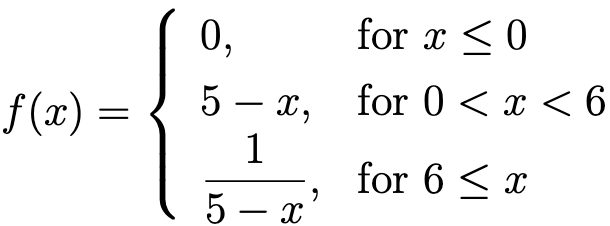

Write your code to plot the graph of $f$ here:

syms x
f0 = piecewise(x <=0, 0, 0 < x < 6, 5-x, 6<=x, 1/(5-x))

$$f0 = \left\{ \begin{array}{cl} 0 & \text{ if }x\leq 0\\ 5-x & \text{ if }x\in \left(0,6\right)\\ -\frac{1}{x-5} & \text{ if }6\leq x \end{array}\right.$$

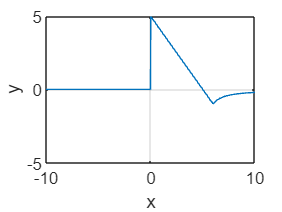

fplot(x, f0, [-10, 10])
grid on, xlabel ('x'), ylabel('y'), axis([-10,10,-5,5])

Where is $f$ discontinuous? Where is $f$ not differentiable?

**Challenge (Optional): **

In your notebook

- First calculate the derivative of $f$.

- Second, determine if $f$ is differentiable at $x=6$ by calculating left-hand and right-hand derivatives. i.e. $f_-^{\prime } \left(6\right)$ and $f_+^{\prime } \left(6\right)$.

Then use MATLAB to confirm your results. Use the method from section 3.1 to *calculate the symbolic derivative* and the method from section 3.2 to *calculate the left-hand and right-hand derivatives*.

**Hint**: You might want to define $f\left(x\right)$ using the method introduced in Appendix A, in order to evalaute the left-hand and right-hand derivatives.

Write your code here:

### Appendix A:

### Alternative method for defining piecewise functions: User-defined functions with `if-else` statements and the `for` loop

In order to define and plot $f\left(x\right)$ we can create our own [MATLAB function](https://au.mathworks.com/help/matlab/ref/function.html) considering two main points:

- Define our function with [`if-else` statements](https://au.mathworks.com/help/matlab/ref/if.html). 

- Use different conditions for the different ranges and assign appropriate values.

Thus our piecewise function $f\left(x\right)$ can be defined as follows:

In MATLAB we **must declare a new **[**function**](https://au.mathworks.com/help/matlab/ref/function.html) before using it in our code. In the case of **Live Scripts**, we can add it at the very end of our document, see Appendix B for more details.

Then we can call our function named `myPiecewiseFunc` to plot the graph of $f\left(x\right)$. So we write:

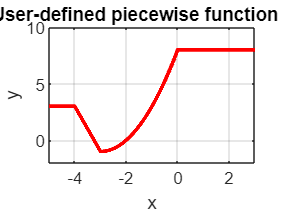

x = linspace(-5, 3, 10000);  % Define domain
y = zeros(1, length(x));     % A place holder for the range

% Now we evaluate element-by element with a "for" loop
for i = 1 : length(x)
    y(i) = myPiecewiseFunc(x(i));
end

% Finally, we just plot it
plot(x, y, 'r', 'LineWidth', 2)
xlabel('x'), ylabel('y'), grid on
title('User-defined piecewise function f(x)')
axis([-5 3 -2 10])

**Remark:** Notice that we have used the [`for`](https://au.mathworks.com/help/matlab/ref/for.html) loop to apply our `myPiecewiseFunc` function to every element in "`x`". Within any program, you can define sections of code that either repeat in a loop or conditionally execute. On the one hand, loops use a [`for` or `while` keyword](https://au.mathworks.com/help/matlab/matlab_prog/loop-control-statements.html). On the other hand, [conditional statements](https://au.mathworks.com/help/matlab/matlab_prog/conditional-statements.html) use [`if`](https://au.mathworks.com/help/matlab/ref/if.html) or [`switch`](https://au.mathworks.com/help/matlab/ref/switch.html), as we did to define our function (see Appendix B).

## Appendix B: User-defined functions

function y = myPiecewiseFunc(x)
  if x <= -4
     y = 3;
  elseif -4 < x && x <= -3
     y = -4*x - 13;
  elseif -3 < x && x <= 0
     y = x^2 + 6*x + 8;
  else
     y = 8;
  end
end

% Write your own functions after this comment



%{ 

References:

- Declaration of functions
  https://au.mathworks.com/help/matlab/ref/function.html

- "If-else" statements
  https://au.mathworks.com/help/matlab/ref/if.html

- Loop control statements
  https://au.mathworks.com/help/matlab/matlab_prog/loop-control-statements.html
  https://au.mathworks.com/help/matlab/ref/for.html

%}